1) Wyznaczanie rozkładu LU

    a) Test metod

A=[5,3,2;1,2,0;3,0,4]

A =      5     3     2
     1     2     0
     3     0     4



[L U]=gauss(A)

L =     1.0000         0         0
    0.2000    1.0000         0
    0.6000   -1.2857    1.0000


U =     5.0000    3.0000    2.0000
         0    1.4000   -0.4000
         0         0    2.2857


LU=L*U

LU =     5.0000    3.0000    2.0000
    1.0000    2.0000         0
    3.0000   -0.0000    4.0000


[L U]=dolittle(A)

L =     1.0000         0         0
    0.2000    1.0000         0
    0.6000   -1.2857    1.0000


U =     5.0000    3.0000    2.0000
         0    1.4000   -0.4000
         0         0    2.2857


LU=L*U

LU =     5.0000    3.0000    2.0000
    1.0000    2.0000         0
    3.0000         0    4.0000


[L U P]=LUP(A)

L =     1.0000         0         0
    0.6000    1.0000         0
    0.2000   -0.7778    1.0000


U =     5.0000    3.0000    2.0000
         0   -1.8000    2.8000
         0         0    1.7778


P =      1     0     0
     0     0     1
     0     1     0


LU=L*U

LU =      5     3     2
     3     0     4
     1     2     0


PA=P*A

PA =      5     3     2
     3     0     4
     1     2     0


    b) Porównanie szybkości metod - 1000 losowych macierzy

iterations=1000;
tic
for i=1:iterations
A=rand(4)*10;
[L,U]=dolittle(A);
end
czasDolittle=toc

czasDolittle = 0.0141


tic
for i=1:iterations
A=rand(4)*10;
[L,U]=gauss(A);
end
czasGauss=toc

czasGauss = 0.0383

    c) Czas obliczania LU obiema metodami dla różnych rozmiarów macierzy A

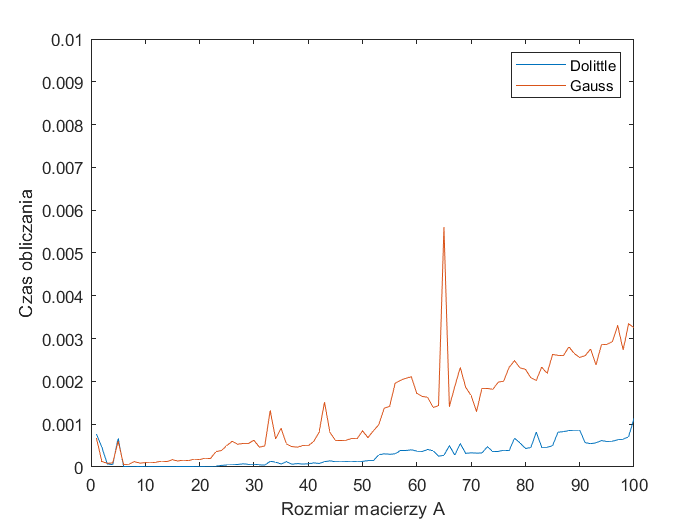

iterations=100;
tDoLittle=zeros(1,iterations);
tGauss=zeros(1,iterations);
x=1:iterations;
for i=1:iterations
A=randi(10,i);
tic
[L,U]=dolittle(A);
tDoLittle(i)=toc;

tic
[L,U]=gauss(A);
tGauss(i)=toc;
end

plot(x,tDoLittle);
hold on;
plot(x,tGauss);
xlabel("Rozmiar macierzy A")
ylabel("Czas obliczania")
legend("Dolittle","Gauss")
ylim([0,0.01]);
hold off;

2) Badanie wpływu zaburzeń

c = logspace(2,10,100);
n = 4;

y_A_element = zeros(1, length(c));
y_A_kolumna = zeros(1, length(c));
y_A_caly = zeros(1, length(c));
y_b_caly = zeros(1, length(c));

delta = randi(10, 1);

for i = 1:length(c)
    [A, b, x] = tstcnd(n, i);

    A_element = A;
    A_element(1, 1) = A(1, 1) + delta;
    x_A_element = linsolve(A_element, b);

    x_b_caly = linsolve(A, b_caly);
    A_kolumna = A;
    A_kolumna(:, 1) = A(:, 1) + delta;
    x_A_kolumna = linsolve(A_kolumna, b)

    A_caly = A + delta;
    x_A_caly = linsolve(A_caly, b);

    b_caly = b + delta;

    %bledy wzgledne x
    dx_A_element = norm(x_A_element) / norm(x);
    dx_A_kolumna = norm(x_A_kolumna) / norm(x);
    dx_A_caly = norm(x_A_caly) / norm(x);
    dx_b_caly = norm(x_b_caly) / norm(x);

    %bledy wzgledne zaburzen
    dblad_A_element = norm(A_element) / norm(A);
    dblad_A_kolumna = norm(A_kolumna) / norm(A);
    dblad_A_caly = norm(A_caly) / norm(A);
    dblad_b_caly = norm(b_caly) / norm(b);

    y_A_element(i) = dx_A_element/dblad_A_element;
    y_A_kolumna(i) = dx_A_kolumna/dblad_A_kolumna;
    y_A_caly(i) = dx_A_caly/dblad_A_caly;
    y_b_caly(i) = dx_b_caly / dblad_b_caly;
end

x_A_kolumna =     1.0000
    2.0000
   -1.0001
   -5.0000


x_A_kolumna =     2.0000
   -2.0001
    4.0001
    0.9998


x_A_kolumna =    -8.9997
    2.0010
    2.0012
    4.0001


x_A_kolumna =     2.9993
   -3.9998
   -0.9996
    3.9999


x_A_kolumna =     2.0004
    3.0001
   -1.0002
   -8.9994


x_A_kolumna =     2.0002
   -1.0001
    4.0004
   -5.0011


x_A_kolumna =     3.0000
    1.9997
    1.0006
   -2.0009


x_A_kolumna =     1.0000
    0.9999
    2.9997
    1.0002


x_A_kolumna =     6.9982
   -1.0005
    2.0010
   -3.9984


x_A_kolumna =    -2.9996
    2.9991
    4.9999
   -2.9995


x_A_kolumna =     2.0000
   -3.9999
   -6.0003
   -3.0017


x_A_kolumna =     7.0021
    2.9996
   -2.9979
   -0.9988


x_A_kolumna =     6.0000
   -3.0011
   -0.9975
    1.9985


x_A_kolumna =    -4.9990
   -0.9981
    0.9997
   -2.0013


x_A_kolumna =    -6.9942
    1.9955
    0.9965
    2.9944


x_A_kolumna =    -1.0002
    0.9999
   -4.9997
   -1.9998


x_A_kolumna =     3.0013
    4.0015
   -5.9988
    2.9984


x_A_kolumna =    -5.9987
    4.9969
   -2.9979
   -2.0027


x_A_kolumna =     3.0009
   -5.9982
   -0.9994
   -3.9979


x_A_kolumna =    -2.9986
   -1.9975
   -2.0028
    0.9983


x_A_kolumna =    -4.9977
   -1.9985
   10.0004
   -2.9971


x_A_kolumna =    -1.0000
    1.0001
   -0.9996
    0.9998


x_A_kolumna =     3.9990
   -7.9999
    5.0010
   -2.0010


x_A_kolumna =     1.0002
    0.9998
    1.0002
   -6.9996


x_A_kolumna =    -5.0062
   -5.9971
  -11.0006
   -0.9966


x_A_kolumna =     2.9991
    8.0010
    1.0005
    1.0003


x_A_kolumna =     1.0000
    1.0007
    1.0002
    1.0001


x_A_kolumna =     3.9936
    4.0011
    3.9962
   -4.0010


x_A_kolumna =     7.0017
   -5.0010
    8.9974
   -1.0020


x_A_kolumna =     8.9964
    4.9891
   -7.0027
    6.0188


x_A_kolumna =    -4.9976
   -2.0063
   -5.0084
   -3.9937


x_A_kolumna =    -7.0013
   -5.0015
   -1.0029
   -5.9995


x_A_kolumna =     5.0076
    0.9889
    1.0075
    7.0016


x_A_kolumna =     6.0072
    3.9944
    7.0071
    0.9968


x_A_kolumna =     3.0001
    4.0017
    3.9994
    1.0001


x_A_kolumna =     5.9935
    1.9986
    1.0060
   -0.9887


x_A_kolumna =    -3.9950
    1.0062
   -4.9985
    3.0055


x_A_kolumna =    -2.9986
    1.0009
   -5.0005
   -0.9995


x_A_kolumna =    -2.9963
   -2.0003
   -3.9954
   -3.9967


x_A_kolumna =     4.0027
    3.0005
    3.9994
    0.9950


x_A_kolumna =    -4.0022
   -3.9919
    2.9924
    1.0024


x_A_kolumna =    -4.9986
    6.9906
   -0.9969
   -6.0077


x_A_kolumna =     7.0049
    0.9991
   -6.0047
    1.9909


x_A_kolumna =     1.0004
   -1.9997
    1.9996
    3.0007


x_A_kolumna =     7.0034
   -6.0093
   -6.9977
   -5.0225


x_A_kolumna =     4.0086
    3.9945
   -2.0072
    1.0108


x_A_kolumna =    -3.0049
    4.9967
   -7.9924
    0.9927


x_A_kolumna =    -7.0001
   -2.0027
    4.0194
    7.0248


x_A_kolumna =    -1.0018
   -7.0001
   -3.0001
    2.9980


x_A_kolumna =     6.0158
   -2.9979
    3.0099
   -1.9813


x_A_kolumna = 4×1
   -5.9909
    5.9988
    2.0005
    0.9970


x_A_kolumna = 4×1
    1.9988
    0.9995
    4.9994
    2.9996


x_A_kolumna = 4×1
    3.0011
   -3.0068
    1.9969
    1.0028


x_A_kolumna = 4×1
   -1.9911
    9.0000
    3.9976
    0.9960


x_A_kolumna = 4×1
   -1.0002
   -4.9995
    3.0002
    5.9998


x_A_kolumna = 4×1
   -1.9953
    2.9989
    8.0070
    5.0009


x_A_kolumna = 4×1
    9.0008
   -5.9965
    3.9997
   -1.9991


x_A_kolumna = 4×1
   -2.0000
   -7.9998
   -4.9941
   -5.9981


x_A_kolumna = 4×1
   -1.0012
    1.0007
    1.0008
    4.0003


x_A_kolumna = 4×1
   -0.9972
   -0.9955
    1.9976
   -7.0010


x_A_kolumna = 4×1
    2.0010
    3.0008
   -2.9919
   -4.0034


x_A_kolumna = 4×1
    3.0018
   -0.9967
    2.9872
    2.0072


x_A_kolumna = 4×1
    7.0018
   -4.0007
    3.0107
    2.0023


x_A_kolumna = 4×1
    3.9975
   -2.0058
   -2.9895
   -1.9949


x_A_kolumna = 4×1
    2.9916
   -8.0047
    2.0034
   -2.0024


x_A_kolumna = 4×1
   -6.0022
   -2.0032
   -4.0002
   -4.9920


x_A_kolumna = 4×1
    2.0044
   -1.9999
    5.0002
   -1.0020


x_A_kolumna = 4×1
   -2.0026
   -2.0063
    3.9986
    2.9929


x_A_kolumna = 4×1
   -4.9972
    3.9881
   -2.9971
    7.0063


x_A_kolumna = 4×1
   -3.9942
    3.9982
    9.0049
    3.0071


x_A_kolumna = 4×1
   -4.0134
   -1.0153
    7.0004
    6.0069


x_A_kolumna = 4×1
   -3.0055
    7.0001
  -11.0057
  -10.0060


x_A_kolumna = 4×1
   -4.0030
   -3.9969
   -1.9965
   -1.9989


x_A_kolumna = 4×1
   -1.0010
   -3.0041
    2.0036
   -1.9984


x_A_kolumna = 4×1
   -6.0052
    2.0007
    0.9943
   -9.9980


x_A_kolumna = 4×1
    4.0211
   -3.0012
   -1.0027
   -2.9985


x_A_kolumna = 4×1
    1.0029
    0.9975
   -6.0057
   -6.0005


x_A_kolumna = 4×1
    4.9921
    3.9864
   -5.0048
    1.9965


x_A_kolumna = 4×1
    0.9990
   -5.9964
   -1.0036
   -1.0048


x_A_kolumna = 4×1
   -3.9998
    1.9912
   -0.9967
    4.0015


x_A_kolumna = 4×1
    3.0039
   -5.0092
   -1.9996
   -1.0005


x_A_kolumna = 4×1
    1.9994
    3.9883
    8.0026
    2.9970


x_A_kolumna = 4×1
    0.9982
    1.9995
    1.0007
    0.9992


x_A_kolumna = 4×1
   -1.9967
    9.0067
   -3.0110
   -1.0000


x_A_kolumna = 4×1
    5.0198
    2.0043
   -1.0006
    2.9939


x_A_kolumna = 4×1
   10.9994
   -5.9810
   -0.9993
   -0.9703


x_A_kolumna = 4×1
    1.9993
   -3.0029
    1.9984
    0.9974


x_A_kolumna = 4×1
    7.0072
    2.0011
    2.0014
    5.0168


x_A_kolumna = 4×1
    2.9984
    4.9961
   -2.9971
    7.9937


x_A_kolumna = 4×1
    2.0015
   -7.0021
   -2.9985
    3.9997


x_A_kolumna = 4×1
    1.0022
   -3.9983
   -4.9964
   -2.0003


x_A_kolumna = 4×1
   -1.9981
    3.0010
   -4.0003
   -1.0012


x_A_kolumna = 4×1
    4.9936
    1.9853
   -1.0200
   -2.0381


x_A_kolumna = 4×1
   -2.9987
    1.0060
    3.0059
   -2.9961


x_A_kolumna = 4×1
    5.9908
    6.9815
    2.9916
    8.9948


x_A_kolumna = 4×1
    4.0135
   -3.9807
   -0.9983
    2.9978


x_A_kolumna = 4×1
   -7.0615
    3.9867
   -3.0104
    3.0180


x_A_kolumna = 4×1
   -0.9998
   -3.0001
    1.9998
    5.9995


x_A_kolumna = 4×1
   -2.9879
    2.0126
    4.0073
  -11.9857


x_A_kolumna = 4×1
    4.9804
   -0.9894
   -2.9789
    0.9997


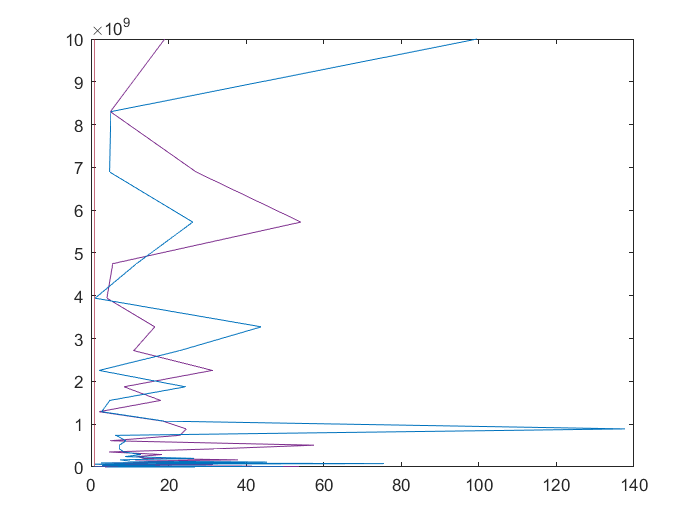

 plot(y_A_kolumna,c)
 hold on;
 plot(y_A_kolumna,c)
 plot(y_A_caly,c)
 plot(y_b_caly,c)

3) Zastosowania rozkładu LU

    a)

Test, czy działa poprawnie

A=randi(10,4)
RozwiniecieLaplacea(A)
det(A)
detLUP(A)

Wykres

iterations=10;
tRozwiniecieLaplacea=zeros(1,iterations);
tDetLUP=zeros(1,iterations);
x=1:iterations;
for i=1:iterations
A=randi(10,i);
tic
[detA]=RozwiniecieLaplacea(A);
tRozwiniecieLaplacea(i)=toc;

tic
[detA]=detLUP(A);
tDetLUP(i)=toc;
end

plot(x,tRozwiniecieLaplacea);
hold on;
plot(x,tDetLUP);
xlabel("Rozmiar macierzy A")
ylabel("Czas obliczania")
legend("Rozwiniecie Laplace'a","Rozklad LU(P)")
ylim([0,0.01]);
hold off;

    b)

inverse_LU(A)

A=rand(3)*10;
[L,U]=gauss(A);
invMATLAB=inv(A)
invInverse_LU=inverse_LU(A)

inverse_LU2(A)

A=rand(3)*10;
invMATLAB=inv(A)
invInverse_LU2=inverse_LU2(A)

porownanieSzybkosci

iterations=10;
tInverse_LU=zeros(1,iterations);
tInverse_LU2=zeros(1,iterations);
x=1:iterations;
for i=1:iterations
A=randi(10,i);
tic
[invA]=inverse_LU(A);
tInverse_LU(i)=toc;

tic
[invA]=inverse_LU2(A);
tInverse_LU2(i)=toc;
end

plot(x,tInverse_LU);
hold on;
plot(x,tInverse_LU2);
xlabel("Rozmiar macierzy A")
ylabel("Czas obliczania")
legend("inverse LU","inverse LU2")
ylim([0,0.01]);
hold off;


[A, b, x] = tstcnd(8,100);
rand(size(b))

ans =     0.7868
    0.2138
    0.2276
    0.7292
    0.7127
    0.2290
    0.3995
    0.5873


norm(b)

ans = 3.2277e+10

        delta = rand(1) * norm(A) / 10

delta = 9.7406e+07